# **drawForce**

Draw a force

## Description

## Syntax

drawForce(F,th,d,xr,yr)

drawForce(F,th,d,xr,yr,rot)

drawForce(__,'-ad',ad)

drawSupport(__,LineSpec) 

p = drawSpring(__)

## Description

## Method

## Arguments

### Input Arguments

**F,th **-- force and its local inclination angle in degrees

** d          **-- disatnce from reference point

**  xr, yr  **-- reference point 

#### Optional input:

** rot       ** -- rotation of distance about reference point in degrees

### Optional Name-Value Pair Input Arguments

**'-ad',ad **- arowhead width (default is 0.2*F). Height is set to width/2. Arrowhead form is  3 (filled arrow)

***LineSpec*** - specifies line properties, see [Line Properties](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.line-properties.html).

### Optional Output Arguments

**p **- structure with key points

## Examples

### Example 1

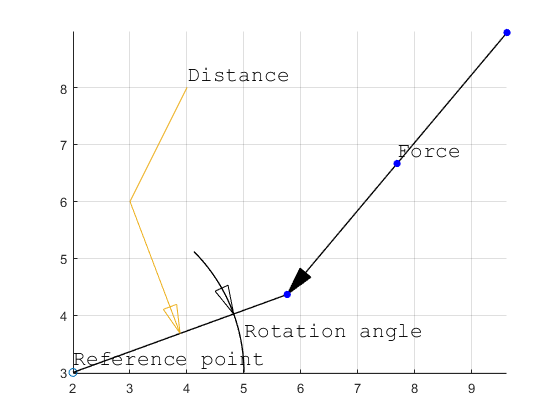

drawInit
gkInit
xr = 2;yr = 3;d = 4; th = 20;
scatter(xr,yr)
drawText(xr,yr,'Reference point')
L=drawLine(xr,yr,'-rtheta',d,th);
L1=drawLeader(2,0.5,0.25,(L.xk(1)+L.xk(2))/2,(L.yk(1)+L.yk(2))/2,[3,4],[6,8]);
drawText(L1.xk(end),L1.yk(end),'Distance')
% draw force inclinaded by 30 degrees to direction
p = drawForce(6,30,d,xr,yr,th,'-ad',0.5);
scatter(p.xk,p.yk,30,'b','filled')
% angular dimension
drawCircle(xr,yr,3,0,th,'-np',40)
drawArcArrow(2,0.5,0.25,xr,yr,3,45,-45+th)
drawText(5,3.5,'Rotation angle')
drawText(p.xk(3),p.yk(3),'Force')
grid on

%axis off
gkClose

### Example 2

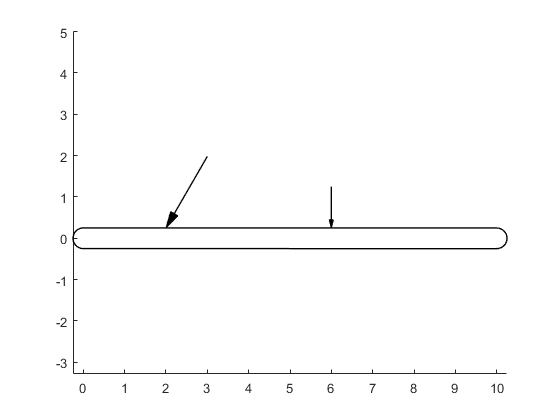

drawInit
gkInit
c=drawCanoe1(0.5,0,0,10,0);
drawForce(2,60,2,c.xk(7),c.yk(7))
drawForce(1,90,6,c.xk(7),c.yk(7))

## **See Also**

## References